close all
clear 
x = (0:1:100).';
y = sin(0.1.*x)*0.3.*x;
n = length(x);


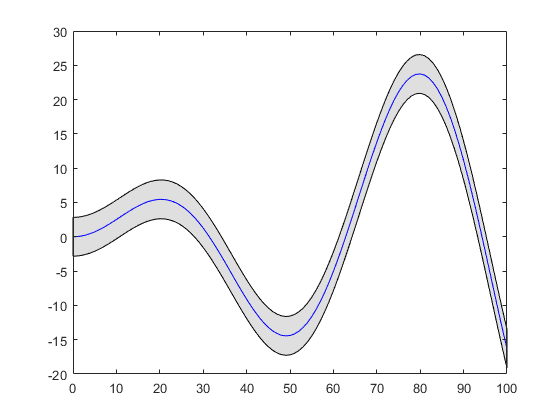

%Level 2: bekannter Mittelwert mit Rauschen überlagert
s2 = 2;
f = [y+2*sqrt(s2); flip(y-2*sqrt(s2),1)];

fill([x;flip(x,1)], f, [7 7 7]/8)
hold on;
plot(x,y,'b')
hold off;

K = CovMatrix(x,0.7,0.8);
DelLogLik([0.7;0.2;0.8],x,y)

ans = 	1.0e+04 *

   -1.7591
   -0.2519
   -0.7616


logLikelihood_V1(y,K,0.2)

ans = -6.4908e+03

Error([0.7;0.2;0.8],x,y)

ans = 5.8533e+03

xS = [x(11);x(21);x(31);x(51);x(61);x(81)];
yS = [y(11);y(21);y(31);y(51);y(61);y(81)];
theta = [1;1;1];% start hyperparameter
[theta, logLike] = scaledConjugateGradient(@Error,@DelLogLik,theta,x,y,10^-6 ,10^-6)

Delta = 0.0481

increase scale
9.


w =     1.2544
    1.1024
    1.1252


r = 	1.0e+05 *

    1.9852
    0.6251
    1.0846


Emin = 1.3149e+03

Delta = 0.0072

increase scale
9.


w =     1.9733
    1.3663
    1.4945


r = 	1.0e+06 *

    1.3444
    0.2527
    0.8592


Emin = 599.2938

Delta = 3.4949e-04

restart
increase scale
9.


w =     2.4250
    1.5205
    1.7347


r = 	1.0e+06 *

    3.3259
    0.4901
    2.2295


Emin = 450.2987

theta =     2.4250
    1.5205
    1.7347


logLike = 450.2987

%Hyperparameter lernen 
meanfunc = [];
covfunc = @covSEiso;
likfunc = @likGauss;
hyp = struct('mean',[],'cov',[0,0],'lik',-0.45);
% 
[likeLog, dLikeLog] = gp(hyp, @infGaussLik, meanfunc, covfunc, likfunc, xS,yS);

'gp' is not found in the current folder or on the MATLAB path, but exists in:
    C:\Users\leppa\Documents\MATLAB\gpml-matlab-master\gpml-matlab-master

Change the MATLAB current folder or add its folder to the MATLAB path.

% 
hyp2 = minimize(hyp, @gp,-100,@infGaussLik,meanfunc, covfunc, likfunc,xS, yS);%W, sigmaF, sigmsN
l = (exp(hyp2.cov(1)));
sigmaF = exp(hyp2.cov(2));
sigmaN = exp(hyp2.lik(1));
[likeLog, dLikeLog] = gp(hyp, @infGaussLik, meanfunc, covfunc, likfunc, xS,yS);

[mu, s2] = gp(hyp2, @infGaussLik, meanfunc, covfunc, likfunc, xS, yS, x);
f = [mu+2*sqrt(s2); flip(mu-2*sqrt(s2),1)];

fill([x;flip(x,1)], f, [7 7 7]/8)
hold on;
plot(x,mu,'b')
plot(xS,yS,'xr')
hold off;

%Level 3: einzelne Funktionswerte bekannt


sigmaF = 1;
sigmaN = 0.2;
l = 10;

K = CovMatrix(xS,sigmaF,l);
K_y = (K+sigmaN^2* eye(length(xS)));

yPredict = zeros(n,1);
s2 = zeros(n,1);
for i = 1: n
    [yPredict(i),s2(i)] = GPpredict_V1(K_y,xS,yS,x(i),sigmaF,sigmaN,l);
end

f = [yPredict+2*sqrt(s2); flip(yPredict-2*sqrt(s2),1)];

fill([x;flip(x,1)], f, [7 7 7]/8)
hold on;
plot(x,yPredict,'b')
plot(xS,yS,'xr')

hold off;

%Level 4 nichts bekannt

function DLL = DelLogLik(w,x,y)
    n = length(y);
    delK = zeros (n,n,3);
    DLL = zeros(3,1);
    
    K = CovMatrix(x,w(1),w(3));
    
    %Del K berechnen
    delK(:,:,2) = 2 * w(2) * eye(n);
    
    for i = 1 : n
        for j = 1: n
        d =(x(i,:)-x(j,:)) * ((x(i,:)-x(j,:)).');
        
        delK(i,j,1) = 2* w(1)          * exp(-1/(2*w(3)^2)*d);
        delK(i,j,3) =  w(1)^2 * d/w(3)^3 * exp(-1/(2*w(3)^2)*d);
        end
    end
    K_inv= chol(K);
    a = K_inv*y;
    DLL(1) = -0.5 * trace((a*a.' - K_inv)*delK(:,:,1));% Hier Optimierung, da nur diagonale Werte übernommen 
    DLL(2) = -0.5 * trace((a*a.' - K_inv)*delK(:,:,2)); 
    DLL(3) = -0.5 * trace((a*a.' - K_inv)*delK(:,:,3));
end

function E = Error(theta,x,y)
    if length(theta) ==3
        sigmaF = theta(1);
        l = theta(2);
        sigmaN = theta(3);
    else
        sigmaN = theta;
        sigmaF= 1;
        l =1;  
    end
    K = CovMatrix(x,sigmaF,l);
    E = - logLikelihood_V1(y,K,sigmaN);
end

